I = imread('rice.png')

I = 256×256 uint8 matrix
   122    92    95    99   102   107    89    90    95   110    91    96    81    87    93    94   106    89   126   104   122   188   192   192   184   172   182   179   178   127   105   110   100   105   119    91   114    99   105   100    94   109    96   102    97    90    92   101   109    92
    99    99   102    82   100    89    91    87    86    94    87    98    92   111    97    93    99    90   102   100   158   185   181   185   179   176   181   181   156   104   107   102   102   103   110    95   104    93   101    95    94   102   100    92    90    88    94   112    95    95
    97   107   103    86    98    92    93    96    96    93   100   121    96   103    89    96   106    94   101   116   181   177   175   175   176   176   178   175   105   104    98   100    91   106   107    98   104    96   103    86   100    97    93   112    97    86    94    96    86   108
   102   100    99    87    97    89   110    95    93    83    89   103

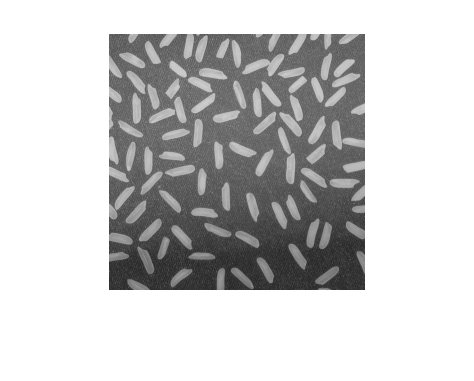

imshow(I)

`Use morphological element "Se" with attribute a disk, of radius 15. This outlines the rice grains. e.i. picks out disk like things in the image. `

se = strel('disk',15);

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [29×29 logical]
    Dimensionality: 2


`Next, ``Imopen`` takes the "se" elements away from image. This provides an approximation for the background.`

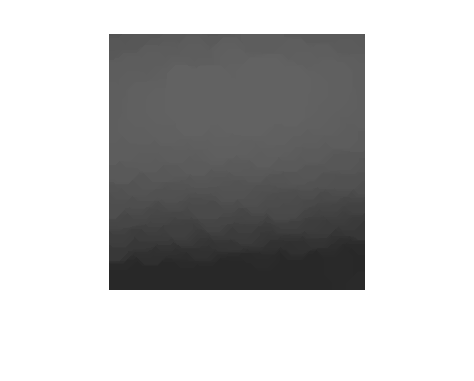

background = imopen(I,se);
imshow(background)

Create new image without the background.

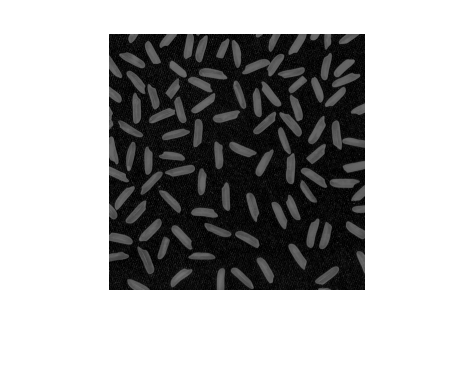

I2 = I - background;
imshow(I2)

%steps can be skipped with I2 = imtophat(I,strel('disk',15));

`Use ``imadjust`` to increase the contrast of the processed image I2 by saturating 1% of the data at both low and high intensities and by stretching the intensity values to fill the uint8 dynamic range.`

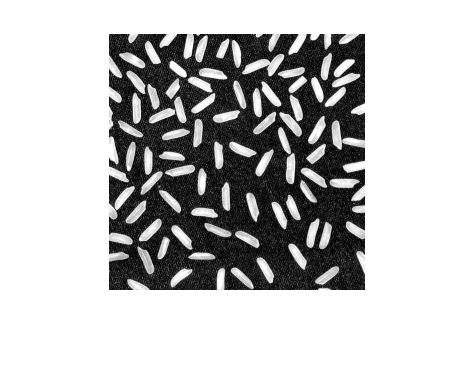

I3 = imadjust(I2);
imshow(I3)

`imbinirize`` turns the saturated image into a binary image. ``areopen`` removes background noise. `

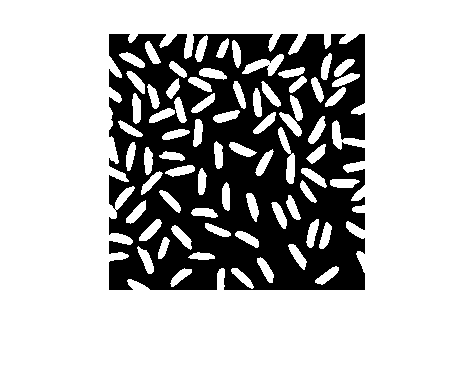

bw = imbinarize(I3);
bw = bwareaopen(bw,50);
imshow(bw)